# Communication Channel Straigth Pipe

#### Parameters

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_r_100um_p_20_tartrazine');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_r_100um_p_20_tartrazine



Parameters

p0 = 20

mu = 9.9792e-04

D_coeff = 4.9000e-10

### Assigning constants

%Channel length
L=L_comm_channel

L = 0.0805

%Channel radius
r=r_comm_channel

r = 1.0000e-04

%Concentration
C_ini=c_NaOH_ini

C_ini = 1000

### Laminar Flow

#### Evaluating the flow velocity

**Description**: This section evaluates the profile velocity from theoretical formulations, which follows the Poiseuile flow. This block also contrasts results with the numerical simulation in COMSOL. The theoretcial velocity profile of the fluid within the pipe yields [2, Eq. 4.9 pag. 54]

$v(r)=\frac{\Delta p}{2\mu L}(2ry-y^2)$, (2)

where $\Delta p$ is the inlet pressure, $\mu$ is the viscosity of the medium (water), $L$ is the length(width) of the pipe, $a$ is the radius of the pipe, and $r$ is the radial-axis coordinates. The case $r=0$ denotes the center in the cross-sectional area of the pipe.

When the inlet speed is given, it specifies the average velocity at the center of the pipe, here denoted as $\bar{v}$, and defined as 

$\bar{v}=\int_0^{a}{v(r)dr}=\frac{2}{3}v_\mathrm{m}$.   (3)

In such a case, the resulting preasure is 

$\Delta p=\frac{3\mu L\bar{v}}{a^2}$, (4)

and the velocity profile can be alternatively evaluated as

$v(r)=\frac{3\bar{v}}{2a^2}(a^2-r^2)$ (5)

#### Theoretical evaluation given the inlet velocity

syms y v
%Evaluating the velocity profile [2, Eq. 4.9 pag. 54]
v(y)=p0/(2*mu*L)*(2*r*y-y^2);

%Center velocity of the fluid
v_center=double(v(r))

v_center = 0.0012

%theoretical calculation of the maximum speed
%v_center=p0/(2*mu*L_comm_channel)*(r_comm_channel^2)

%Mean velocity of the fluid
%[1, Eq. (2.33a) pp.28]
v_mean=r^2*p0/(3*mu*L);
%theoretical calculation of the mean velocity
% v_mean=double(int(v(y),y,0,2*r_comm_channel)/(2*r_comm_channel))

figure;
r_vector=linspace(0,2*r,100);
plot(r_vector*10^6,double(subs(v,y,r_vector))*10^3,'LineWidth',2); grid on; hold on
xlabel('$y$-axis [$\mu$m]','Interpreter','latex');
ylabel ('Velocity [cm/s]','Interpreter','latex');
legend('Theoretical formulation','COMSOL simulation')

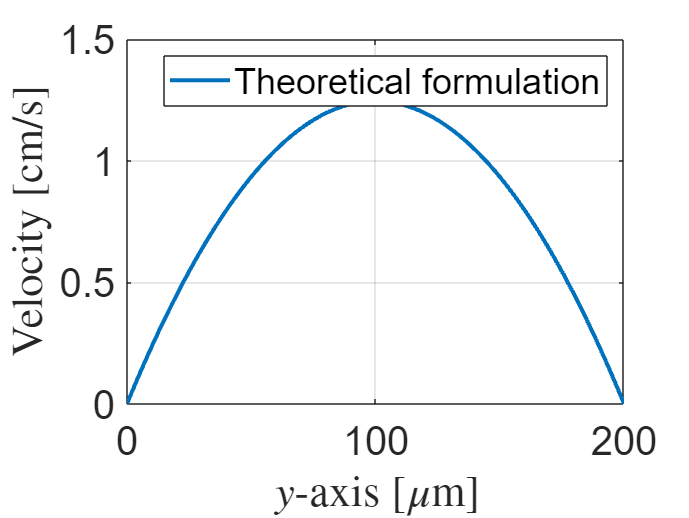

set(gca,'FontSize',fontsize);

### Straight Pipe: Concentration level

**Description**: This section evaluates the concentration level observed at the ouptup of the rectangular pipes (straigth and turning). The evaluation is performed theoretical and following the simulations provided by COMSOL. Following COMSOL simulation we have the following files

- `CH3COOH_versus_L.csv`: This file stores the average concentration for the outlet line, which is placed at `L_inner `in the $x$ axis. The first column is time, and the concentration values are stored in the second column.

#### Theoretical evaluation of concentration in the straight channel

**Description:** Regarding the theoretical calculation we follow the Taylor's model, see [1, Sec. 4.5]. Whenever the Péclet number fulfill the condition in the above Eq. (1), the particles difussion is homogeneous along the $x$-axis and can be evaluated with the non-convection condition, i.e., free difussion in moved coordinate system. For the free difussion scenario, we regard to the case where there the diffusing substance concentrated initially on the negative side of $x'$, where $x'$ refers to the moving coordinates. The moving coordinates is along the $x$ axis of the unmoved coordinates and moves at the average speed of the velocity profile. Considering the initial conditions [3, Sec. 2.2.3 pp. 13]

$C=C_0$, $x'<0$, $C=0$, $x'>0$, $t=0$, (7)

the solution to the diffusion equation yields [3, Eq. (2.14)]

$C(x',t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x'}{2\sqrt{Dt}}$.             (8)

Then, within the moved coordinate system $x'=x-v_0t$ and $D=D_\mathrm{eff}$, yielding

$C(x,t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x-v_0t}{2\sqrt{D_\mathrm{eff}\,t}}$,          (9)

where [1, Eq. (4.54) pp. 77]

$D_\mathrm{eff}=\frac{r^2v_0^2}{48D}$,                                   (10)

is the effective diffusion coefficient, and $v_0$ is the characteristic speed, here given as the average speed within the microfluidic pipe.

#### Mean velocity [2, pag. 54]

v_char=v_mean;

#### Effective Diffusion Coefficient

v_char

v_char = 8.2989e-04

%[1, Eq.(4.54) pp.77]
% D_eff=radius_cylinder_1^2*v_char^2/3/D_NaOH
D_eff=r^2*v_char^2/48/D_coeff

D_eff = 2.9282e-07


%Evaluating the dispersion along the x axis
r^2/D_coeff

ans = 20.4082

%Evaluating the dispersion along the y axis
L^2/D_coeff

ans = 1.3225e+07

#### Concentration Theoretical calculation

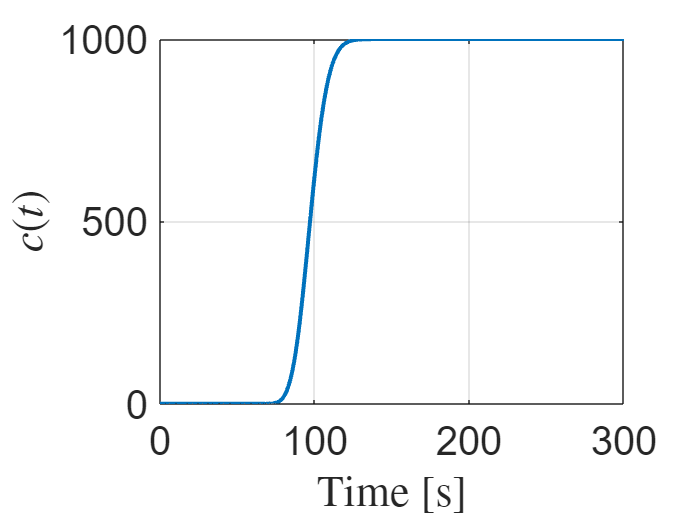

%Matlab code to evaluate the integral
syms t z x Delta_r rd C_amp real
C_straight=C_amp*1./2.*erfc((L-v_char*t)./(2*sqrt(D_eff*t)));

figure;
fplot(subs(C_straight,C_amp,C_ini),[t_ini,300],'LineWidth',2); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel('$c(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Channel impulse response

**Description:** This block evaluates the channel impulse response $h(t)$ for the turning channel. The $h(t)$ sequence is evaluated using the above formulation for the observed concentration of molecules. The above formulation is the step response of the channel when $C_0=1$, as such, the channel impulse response can be evaluated as [4, Eq. (7b), pp. 78]

$h(t)=\frac{\partial}{\partial t}C(x,t)\bigg|_{C_0=1}$,  (7)

where $C(x,t)$ is given as in Eq. (3) above.

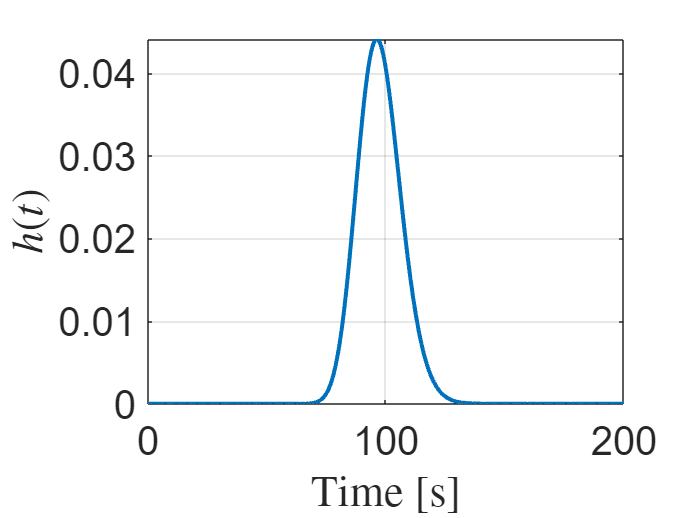

h_straight=subs(diff(C_straight,t),C_amp,1);

figure;
fplot(h_straight,[t_ini,200],'LineWidth',2); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel('$h(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

#### Transmitted sequence

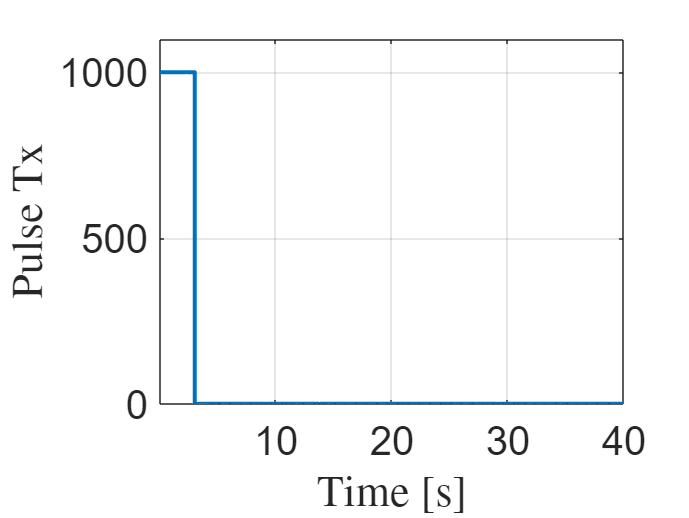

% Pulse from t=0 to t=Tg, amplitude = cg:
pulse_Tx = c_pulse * (heaviside(t) - heaviside(t - Tg));
figure;
fplot(pulse_Tx,[t_ini,300],'LineWidth',2); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Pulse Tx','Interpreter','latex');
axis([t_ini t_end 0 1.1*c_pulse])
set(gca,'FontSize',fontsize);

#### Received sequence

**Description**: This block evaluates the received sequence with the convolution of the transmitted pulse and the CIR sequence.

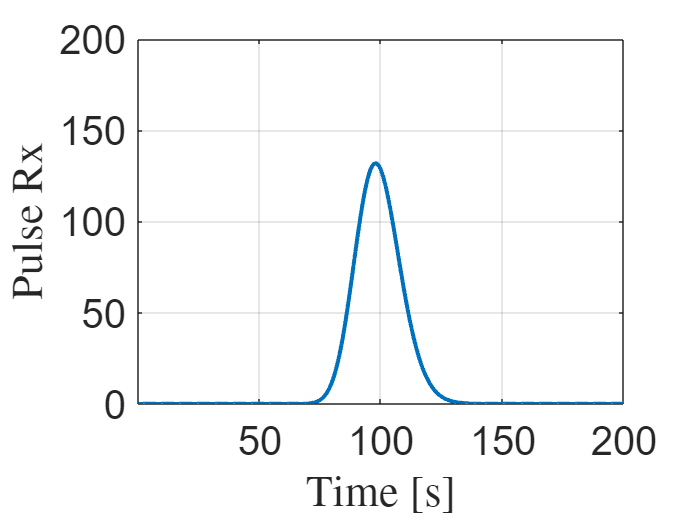

total_points_time=1e3;
t_ini=1e-7;
t_end=200;
t_vec = linspace(t_ini,200,total_points_time);

pulse_Rx=conv(double(subs(pulse_Tx,t,t_vec)),double(subs(h_straight,t,t_vec)))*(t_vec(2)-t_vec(1));

figure;
time_plot=(1:length(pulse_Rx))*(t_vec(2)-t_vec(1));
plot(time_plot,pulse_Rx,'LineWidth',2); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Pulse Rx','Interpreter','latex');
axis([t_ini t_end 0 0.2*c_pulse])
set(gca,'FontSize',fontsize);

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end